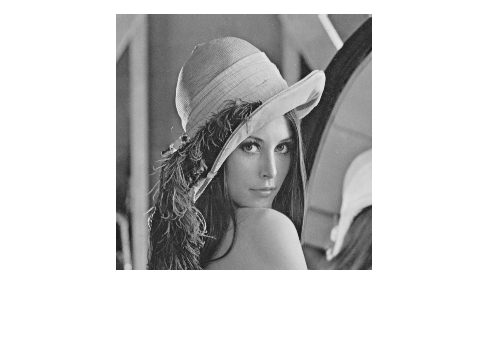

img = imread("../images/lena_gray_256.tif");
imshow(img)

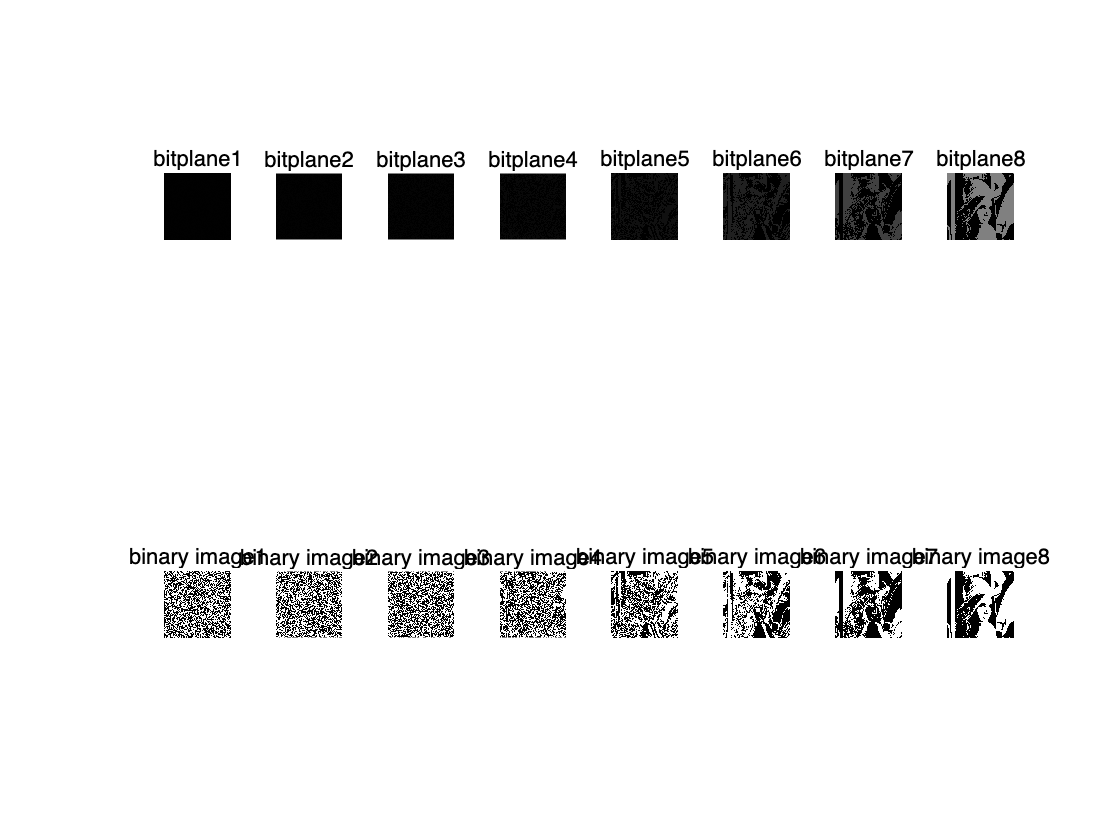

figure;
for i = 0:7
%   get i-th bit map by performing bitwise AND operation
    bit_map = bitand(img, 2^i);
    subplot(2, 8, i+1)
    imshow(bit_map)
    title("bitplane"+int2str(i+1));
    subplot(2, 8, 8 + (i+1))
%   adjust intensity interval for visualization purposes
    imshow(bit_map / 2^i * 255)
    title("binary image"+int2str(i+1))
end